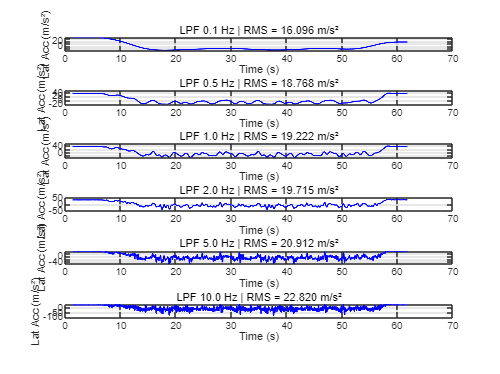

% === Load IMU Data ===
data = readtable('imu1.csv');
t = data.Time_ms / 1000;                  
Ay = data.AccelY_g / 100 * 9.80665;        % 단위 수정 후 중력 보정
Ay = Ay - mean(Ay);

% === Sampling Frequency ===
fs = 1 / mean(diff(t));

% === Cutoff Frequencies ===
cutoff_list = [0.1, 0.5, 1, 2, 5, 10];
n = length(cutoff_list);
filtered_Ay = zeros(length(Ay), n);
rms_values = zeros(n, 1);

% === Filtering & RMS
for i = 1:n
    fc = cutoff_list(i);
    [b, a] = butter(4, fc / (fs/2));
    filtered = filtfilt(b, a, Ay);
    filtered_Ay(:, i) = filtered;
    rms_values(i) = rms(filtered);
end

% === Plot
figure;
for i = 1:n
    subplot(n, 1, i);
    plot(t, filtered_Ay(:, i), 'b', 'LineWidth', 1.2);
    title(sprintf('LPF %.1f Hz | RMS = %.3f m/s²', cutoff_list(i), rms_values(i)));
    xlabel('Time (s)');
    ylabel('Lat Acc (m/s²)');
    grid on;
end


% === Summary Table
T_rms = table(cutoff_list', rms_values, ...
    'VariableNames', {'Cutoff_Hz', 'Lat_Accel_RMS_mps2'});
disp(T_rms);

    Cutoff_Hz    Lat_Accel_RMS_mps2
    _________    __________________

       0.1             16.096      
       0.5             18.768      
         1             19.222      
         2             19.715      
         5             20.912      
        10              22.82      

